# Occlusion

#### Fred liu 2022.5.20

**載入模型與影像(Load Model & Image)**

net = resnet50;
img = imread("t03.jpg");

**影像辨識(Image Classify)**

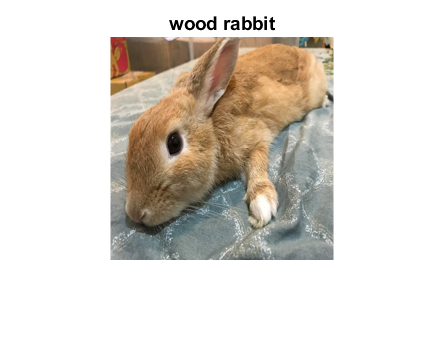

inputSize = net.Layers(1).InputSize(1:2);
re_img = imresize(img,inputSize);
figure,imshow(re_img)

[label,scores] = classify(net,re_img);
title(char(label))

**影像可視化(Image Occlusion)**

scoreMap = occlusionSensitivity(net,X,label);

**顯示熱圖(Show ScoreMap)**

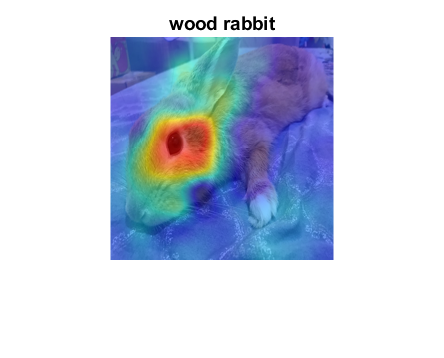

figure
imshow(X),hold on
imagesc(scoreMap,'AlphaData',0.5);
colormap jet
title(char(label))

**前三高類別(Top 3 Class)**

%% List top 3 class scores
[ssort, sidx] = sort(scores, 'descend');

numTopClasses = 3; % show top N choices
TopClasses = net.Layers(end).ClassNames(sidx(1:numTopClasses));
TopScores = ssort(1:numTopClasses)';

topTable = table(TopClasses, TopScores)

topTable = 3×2 table
      TopClasses       TopScores
    _______________    _________

    {'wood rabbit'}     0.61167 
    {'hare'       }     0.24916 
    {'Angora'     }     0.13827 


**第二高類別顯示(Second Class Show)**

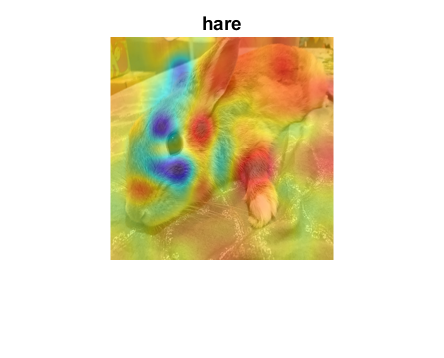

%% 
scoreMap = occlusionSensitivity(net,X,TopClasses{2});
%%
figure,imshow(X)
hold on
imagesc(scoreMap,'AlphaData',0.5);
colormap jet
title(char(TopClasses{2}))